# 需求分析：制作GIF动图

- 绘制曲线并生成 gif 图；

- 现有图片生成 gif 图。

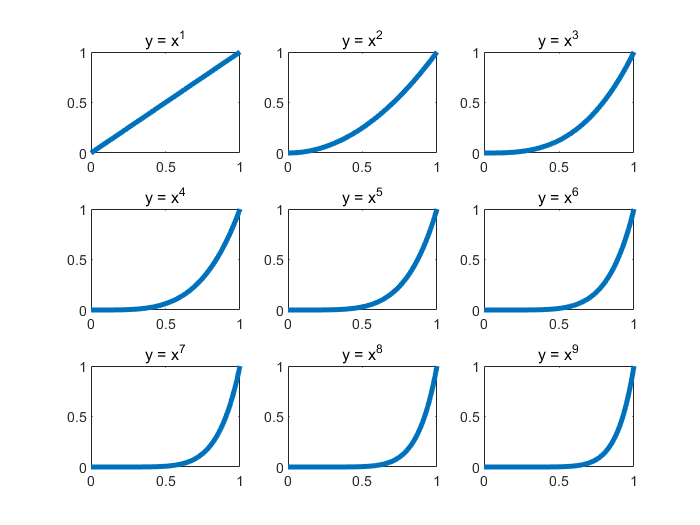

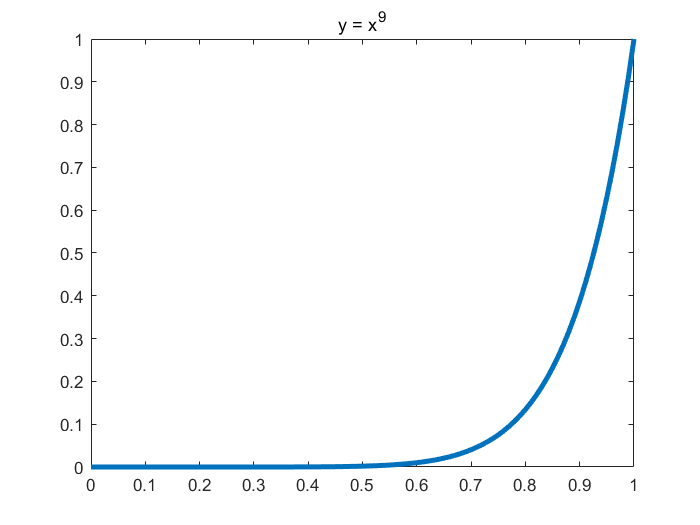

clear; clc;
x = 0:0.01:1;
n = 1:9;
len = length(n);
im = cell(1, len);
% 单独显示每个图
figure;
for idx = 1:len
    subplot(3, 3, idx)
    plot(x, x.^idx, 'LineWidth',3)
    title(['y = x^', num2str(idx)])
end
% 获取绘制对象
fig = figure;
for idx = 1:len
    y = x.^idx;
    plot(x, y, 'LineWidth', 3)
    title(['y = x^', num2str(n(idx))])
%     drawnow
%     pause(0.1);
    frame = getframe(fig);
    im{idx} = frame2im(frame);
end

% 输出文件名
filename = 'testAnimated.gif'; 
for idx = 1:len
    % 制作gif文件，图像必须是index索引图像
    [A, map] = rgb2ind(im{idx}, 256);
    if idx == 1
        imwrite(A, map, filename, 'gif', 'LoopCount', Inf, 'DelayTime', 0.3);
    else
        imwrite(A, map, filename, 'gif', 'WriteMode', 'append', 'DelayTime', 0.3);
    end
end

clear;clc;
% 保存文件名
filename = 'Model.gif';  
% 4张图
for i = 1:4
    % 图片路径
    fileName = [num2str(i), '.jpg'];      
    img = imread(fileName);
    % 重定义尺寸
    img = imresize(img, [256, 256]);      
    imshow(img);
    % 不显示窗口
    set(gcf, 'visible', 'off');   
    % 获取位置
    q = get(gca, 'position');  
    % 设置左边距离值为零
    q(1) = 0;  
    % 设置右边距离值为零
    q(2) = 0;     
    % 重新设置位置
    set(gca, 'position', q);
    frame = getframe(gcf, [0, 0, 200, 200]);  
    im = frame2im(frame);      
    imshow(im);
    [I, map] = rgb2ind(im, 256);
    if i == 1
        imwrite(I, map, filename, 'gif', 'Loopcount', inf, 'DelayTime', 0.3);
    else
        imwrite(I, map, filename, 'gif', 'WriteMode', 'append', 'DelayTime', 0.3);
    end
end